## THIS DOESN'T WORK!! look at qp_trajectory2

% It optimises the cost function of SUM (xr-x)^2 + u^2
% There is a constraint on 

k_track = 1;
k_effort = 0.001;%0.0001;

% number of data points
N = 200;

% reference x = step funciton 
xr = ones(N, 1);
for i = 1:N
    xr(i) = sin(5*Ts*i);
end

% initial condition
x0 = [0 0];

A = [1 Ts; 0 1];
B = [0; Ts];

mat = zeros(2, N);

u_lim = 0.1*Ts;

for i = 1:N
    mat(:,i) = (A^(i-1))*B;
end

H = 2*eye(2*N-1); % x2 to counteract the 1/2 coefficient in the solver

for i = 1:2*N-1 
    if i <= N
        H(i,i) = k_track*H(i,i);    
    else
        H(i,i) = k_effort*H(i,i);
    end
end

f = zeros(2*N-1,1);

for i = 1:N
    f(i) = -2*xr(i);
end

Aineq = [];
bineq = [];
Aeq = zeros(2*N-1);
beq = zeros(2*N-1, 1);
lb = zeros(2*N-1,1);
ub = zeros(2*N-1,1);

% set values in Aeq
Aeq(1,1) = 1;

for i = 2:N
    Aeq(i,i) = -1;
end

for i = 2:N
    Aeq(i, 1) = [1,0]*A^(i-1)*[1;0]; 
    
    p = zeros(1, N-1);
    p(1:i-1) = mat(1, 1:i-1);
    Aeq(i,N+1:end) = p;
end

beq(1) = x0(1);
for i = 2:N
    beq(i) = [0,1]*A^(i-1)*[0;1]*x0(2);
end

u_lim = Ts*1000;
for i = 1:2*N-1
    if i <= N
        lb(i) = -inf;
        ub(i) = inf;
    else
        lb(i) = -1*u_lim;
        ub(i) = u_lim;
    end
end

tic;
[z,fval,exitflag,output,lambda] = ...
   quadprog(H,f,Aineq,bineq,Aeq,beq,lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.636931 seconds.


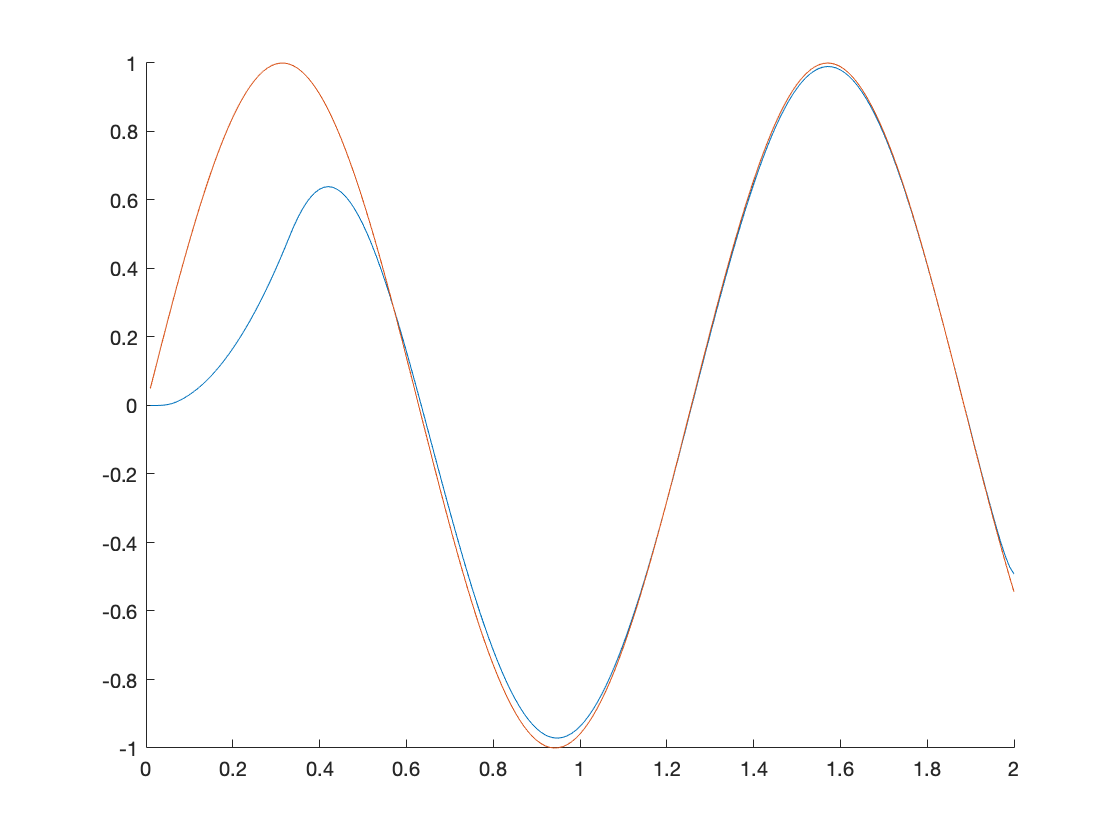


% plotting now
t = ones(N, 1);
for i = 1:N
    t(i) = i*Ts;
end

u = z(N+1:end);
x = z(1:N);

figure;
hold on;
plot(t, x);
plot(t, xr);

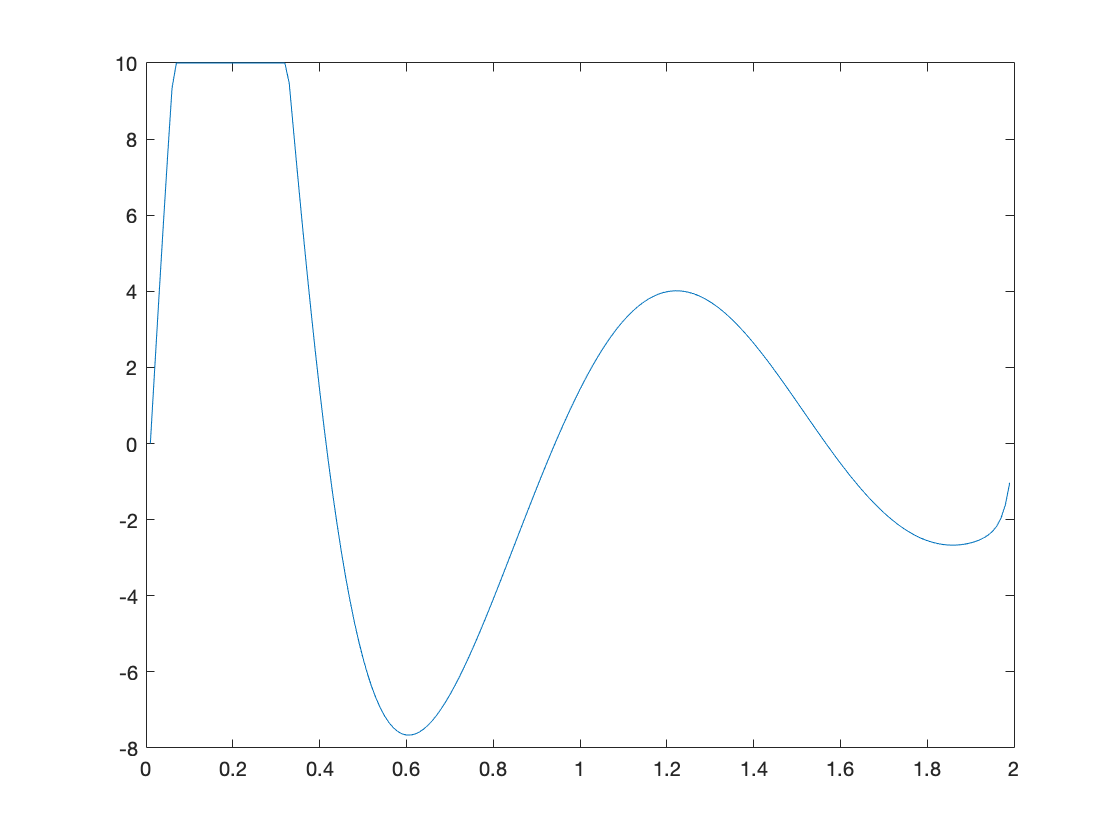


figure;
plot(t(1:end-1), u);